# Cours 14.12.22

t = (1950:10:2020)'

t =         1950
        1960
        1970
        1980
        1990
        2000
        2010
        2020


P = [150.697, 179.323, 203.212, 226.505, 249.633, 281.422, 309.163, 329.5]'

P =    1.5070e+02
   1.7932e+02
   2.0321e+02
   2.2650e+02
   2.4963e+02
   2.8142e+02
   3.0916e+02
   3.2950e+02


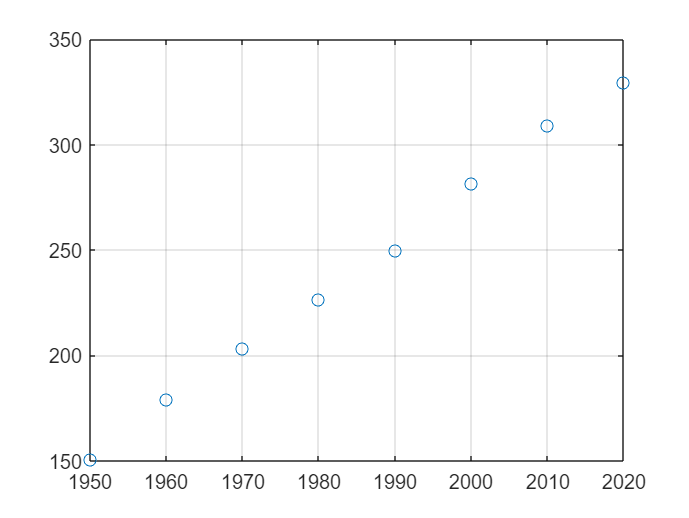


plot(t, P, 'o'); grid on;

## Méthode des moindres carrés

% Ajustemen de droite

A = [t, t.^0]

A =         1950           1
        1960           1
        1970           1
        1980           1
        1990           1
        2000           1
        2010           1
        2020           1



B = A'*A

B =     31526000       15880
       15880           8


b = A'*P

b =    3.8408e+06
   1.9295e+03



% Solution au sens des moindres carrés
x = B\b

x =    2.5697e+00
  -4.8597e+03


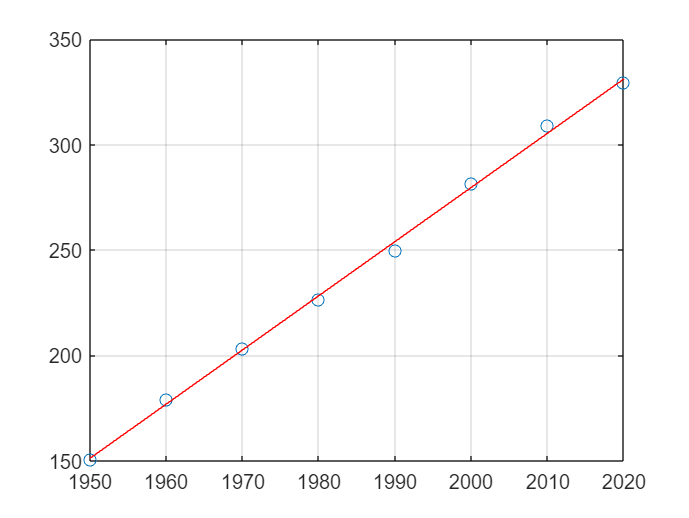


tt = linspace(1950, 2020);
pp = polyval(x, tt);

plot(t, P, 'o', tt, pp, 'r'); grid on;



% On fait passer une parabole au travers du nuage de points
A = [t.^2, t, t.^0]

A =      3802500        1950           1
     3841600        1960           1
     3880900        1970           1
     3920400        1980           1
     3960100        1990           1
     4000000        2000           1
     4040100        2010           1
     4080400        2020           1



B = A'*A

B =    1.2430e+14   6.2596e+10   3.1526e+07
   6.2596e+10   3.1526e+07   1.5880e+04
   3.1526e+07   1.5880e+04   8.0000e+00


b = A'*P

b =    7.6463e+09
   3.8408e+06
   1.9295e+03



x = B\b

x =    9.0911e-04
  -1.0394e+00
  -1.2781e+03



% On s'intéresse au nombre de condition de B
cond(B) % exposant 21 => 21 chiffres sont faux, donc tous

ans =    1.1485e+21


cond(B)*eps % On perds toute la précision car l'exposant est positif !!

ans =    2.5502e+05


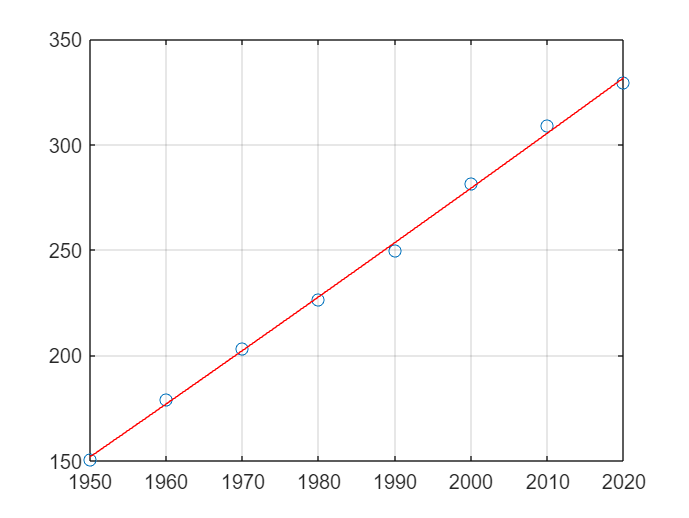


pp2 = polyval(x, tt);
plot(t, P, 'o', tt, pp2, 'r'); grid on;

## Pour améliorer le nombre de condition, on fait un changement d'échelle

% 1950 -> 2020 est transformé en 0 -> 1
z = linspace(0, 1, 8)'

z =             0
   1.4286e-01
   2.8571e-01
   4.2857e-01
   5.7143e-01
   7.1429e-01
   8.5714e-01
   1.0000e+00


% ou :
% z = (t- min(t)) / max(t- min(t)) 

A2 = [z.^2, z, z.^0] % A2 a des valeurs uniquement entre 0 et 1

A2 =             0            0   1.0000e+00
   2.0408e-02   1.4286e-01   1.0000e+00
   8.1633e-02   2.8571e-01   1.0000e+00
   1.8367e-01   4.2857e-01   1.0000e+00
   3.2653e-01   5.7143e-01   1.0000e+00
   5.1020e-01   7.1429e-01   1.0000e+00
   7.3469e-01   8.5714e-01   1.0000e+00
   1.0000e+00   1.0000e+00   1.0000e+00


A % Comparaison avec A

A =      3802500        1950           1
     3841600        1960           1
     3880900        1970           1
     3920400        1980           1
     3960100        1990           1
     4000000        2000           1
     4040100        2010           1
     4080400        2020           1



B2 = A2' * A2

B2 =    1.9475e+00   2.2857e+00   2.8571e+00
   2.2857e+00   2.8571e+00   4.0000e+00
   2.8571e+00   4.0000e+00   8.0000e+00


B % Comparaison avec B

B =    1.2430e+14   6.2596e+10   3.1526e+07
   6.2596e+10   3.1526e+07   1.5880e+04
   3.1526e+07   1.5880e+04   8.0000e+00



% Vérification du nombre de condition
cond(B2)

ans =    3.4116e+02


cond(B)

ans =    1.1485e+21


% On ne perds plus que 2 décimales à la fin au lieu de 21

b2 = A2'*P

b2 =    8.4359e+02
   1.1189e+03
   1.9295e+03


x2 = B2\b2

x2 =    4.4546e+00
   1.7543e+02
   1.5188e+02


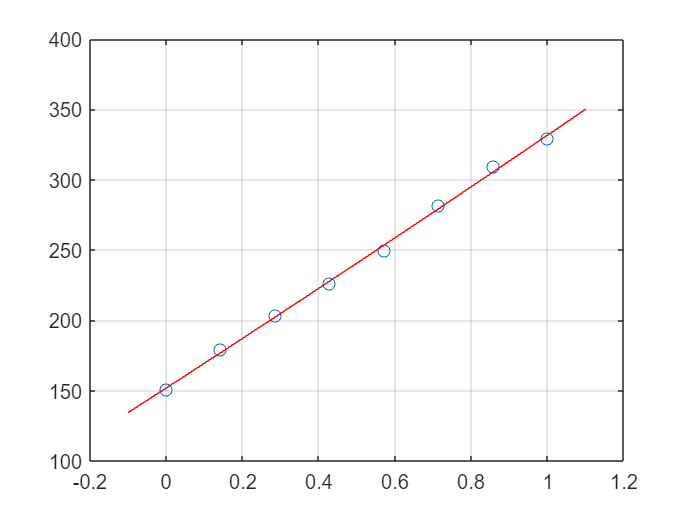

% Avec le changement d'échelle, les paramètres sont évidemment différents
% Mais on peut ajuster le résultat

zz = linspace(-0.1, 1.1, 100);
pp = polyval(x2, zz);

plot(z, P, 'o', zz, pp, 'r'); grid on;


% En 2030 : 
polyval(x2, 1 + 1/7)

ans =    3.5818e+02


## Avec polyfit

t = (1950:10:2020)'

t =         1950
        1960
        1970
        1980
        1990
        2000
        2010
        2020


P

P =    1.5070e+02
   1.7932e+02
   2.0321e+02
   2.2650e+02
   2.4963e+02
   2.8142e+02
   3.0916e+02
   3.2950e+02



% Ajustement au sens des moindres carrés avec polyfit
x = polyfit(t, P, 1)

x =    2.5697e+00  -4.8597e+03


% de degré 2
x = polyfit(t, P, 2) % Mal conditionnée mais n'affiche pas l'erreur

x =    9.0911e-04  -1.0394e+00  -1.2781e+03



x = polyfit(z, P, 2)

x =    4.4546e+00   1.7543e+02   1.5188e+02



% Polyfit ajuste un polynôme ! Pour un autre modèle, utiliser les équations
% normales

## Avec la matrice A sans passer par les équations normales

A

A =      3802500        1950           1
     3841600        1960           1
     3880900        1970           1
     3920400        1980           1
     3960100        1990           1
     4000000        2000           1
     4040100        2010           1
     4080400        2020           1


x2 = A\P

x2 =    9.0911e-04
  -1.0394e+00
  -1.2781e+03



% On est plus précis comme ceci
cond(B)

ans =    1.1485e+21


cond(A)

ans =    3.3890e+10


## Test avec une droite + une sinusoidale

Hors cours

clear;clc;close; 

t = (1950:10:2020)'

t =         1950
        1960
        1970
        1980
        1990
        2000
        2010
        2020


P = [150.697, 179.323, 203.212, 226.505, 249.633, 281.422, 309.163, 329.5]'

P =    1.5070e+02
   1.7932e+02
   2.0321e+02
   2.2650e+02
   2.4963e+02
   2.8142e+02
   3.0916e+02
   3.2950e+02



A = [cos(t) t t.^0]

A =   -5.9860e-01   1.9500e+03   1.0000e+00
   9.3806e-01   1.9600e+03   1.0000e+00
  -9.7559e-01   1.9700e+03   1.0000e+00
   6.9912e-01   1.9800e+03   1.0000e+00
  -1.9764e-01   1.9900e+03   1.0000e+00
  -3.6746e-01   2.0000e+03   1.0000e+00
   8.1429e-01   2.0100e+03   1.0000e+00
  -9.9903e-01   2.0200e+03   1.0000e+00


x = A\P

x =    1.2751e+00
   2.5735e+00
  -4.8672e+03



tt = linspace(1950, 2020, 100)

tt =    1.9500e+03   1.9507e+03   1.9514e+03   1.9521e+03   1.9528e+03   1.9535e+03   1.9542e+03   1.9549e+03   1.9557e+03   1.9564e+03   1.9571e+03   1.9578e+03   1.9585e+03   1.9592e+03   1.9599e+03   1.9606e+03   1.9613e+03   1.9620e+03   1.9627e+03   1.9634e+03   1.9641e+03   1.9648e+03   1.9656e+03   1.9663e+03   1.9670e+03   1.9677e+03   1.9684e+03   1.9691e+03   1.9698e+03   1.9705e+03   1.9712e+03   1.9719e+03   1.9726e+03   1.9733e+03   1.9740e+03   1.9747e+03   1.9755e+03   1.9762e+03   1.9769e+03   1.9776e+03   1.9783e+03   1.9790e+03   1.9797e+03   1.9804e+03   1.9811e+03   1.9818e+03   1.9825e+03   1.9832e+03   1.9839e+03   1.9846e+03


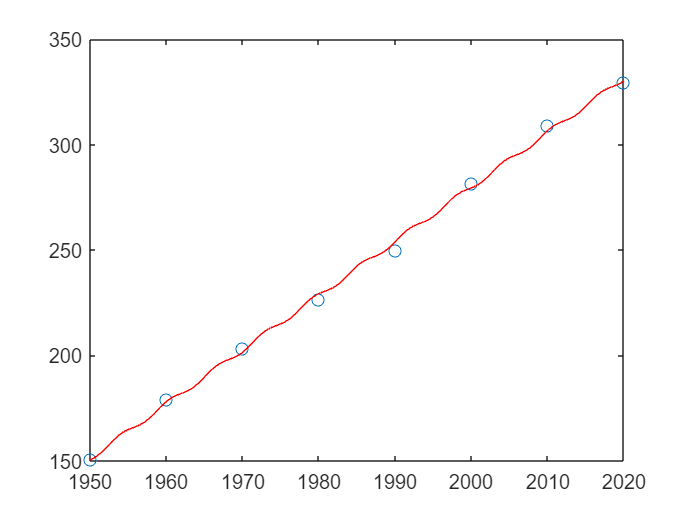

p = @(l) x(1)*cos(l) + x(2)*l + x(3);
y = p(tt);

plot(t, P, 'o', tt, y, 'r')


% Calcul des erreurs (somme des carréa des résidus)
err = norm(p(t) - P)

err =    6.4253e+00
